# Sygnały rzeczywiste

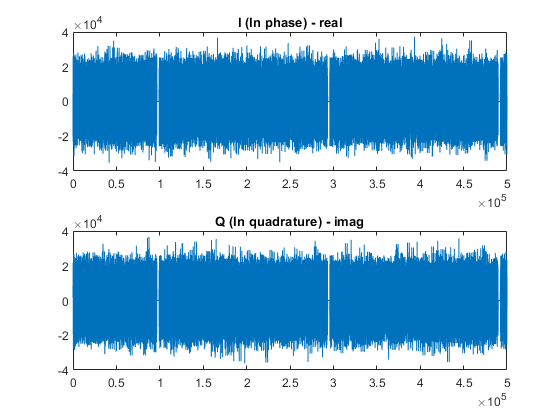

  ReadSize = 500000;      % max 500000
  fs_file = 2.048e6;      % częstotliwość próbkowania w zbiorze
  fs = 2.048e6;           % częstotliwość próbkowania DAB

% ReadFile = fopen('DAB_real_2.048MHz_IQ_float.dat', 'rb');  % rzeczywisty odebrany DAB ("brudny" - zaszuminy, ...)
  ReadFile = fopen('DAB_synt_2.048MHz_IQ_float.dat', 'rb');  % rzeczywisty nadawany DAB ("czysty" - niezaszumiony,...)

  iq = fread( ReadFile, [2, ReadSize], 'float' );
  x = iq(1,:) + iq(2,:)*1i;
  [r, c] = size(x);
  x = reshape(x, c, r);
  if( fs_file ~= fs )
      x = resample(x, fs/1e3, fs_file/1e3);     % signal resampling from fs_file to fs (page 145)
  end
  
  figure;
  subplot(211); plot(real(x)); title('I (In phase) - real');
  subplot(212); plot(imag(x)); title('Q (In quadrature) - imag');

[https://sdr.kt.agh.edu.pl/sdrdab-decoder/null.html](https://sdr.kt.agh.edu.pl/sdrdab-decoder/null.html)

[https://sdr.kt.agh.edu.pl/sdrdab-decoder/phase_reference.html](https://sdr.kt.agh.edu.pl/sdrdab-decoder/phase_reference.html)